addpath('Kinematics')
addpath('Kinetics')
addpath('Control System')
addpath('Control System\Setpoint Control No FF')

supressed_print= evalc('run Linearize_EOMs.mlx'); %Run the script to generate the equations of motion for the Ball and Plate in terms of the u-joint torques

clear supressed_print

sympref('FloatingPoint',true);

# Linear Moving Setpoint Controller

The feasibility of a setpoint controller for trajectory tracking is explored in this script. A traditional setpoint controller architecture is employed but the setpoint is not simple. The setpoint is chosen as the desired trajectory in x and y as functions of time. 

## Augmented System For State Space Representation of an Integral Controller

### Define Augmented State Vector


$$\tilde{x}_{1a} = [
 \int_0^t \!e_x\, \mathrm{d}t~x ~\dot{x} ~\beta~\dot{\beta}]^T


$$


Where $e_x$ is the error in the $x$ position of the ball relative to $x_s$, the setpoint,


$$e_x = x_s - x$$


### Get Matrices for Augmented Dynamics

The new dynamics are found by differentiating the augmented state vector:


$$\dot{\tilde{x}}_{1a}  = 

\left\lbrack \begin{array}{c}

e_x\\ \dot{x}\\ \ddot{x}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack

= 

\left\lbrack \begin{array}{c}

x_s - x\\ \dot{x}\\ \ddot{x}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack$$


This produces a matrix equation with the following form:


$$\dot{\tilde{x}}_{1a} = A_{1a}\tilde{x}_{1a} + B_{1a}T_\beta + S_{1a}{x}_{s}$$


$A_{1a}$ is the $A_1$ matrix modified to contain the dynamics of the $\int_{0}^{t}e_xdt~$term. This term's dynamics are the error itself, $e_x$, so the augmentation is a simple one. 

A1a = [zeros(5,1),[-1 0 0 0; A1]] %Augmented A1 Matrix

$$A1a = \left[\begin{array}{ccccc} 0 & -1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & -5.2170 & 0 & 4.0111 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & 112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

$B_{1a}$ is the direct influence of the actuation torque on the system. Since the integral of the error is not a direct function of this signal, the augmented matrix recieves another zero element. 

B1a = [0;B1]

$$B1a = \left[\begin{array}{c} 0\\ 0\\ -17.7268\\ 0\\ 383.5785 \end{array}\right]$$

$S_{1a}$ is the matrix that tells how the setpoint $x_s$ enters into the dynamics. It essentially derives from the definition of the error term and partially determines the dynamics of the $\int_{0}^{t}e_xdt~$term. 

S1a = sym([1;0;0;0;0])

$$S1a = \left[\begin{array}{c} 1\\ 0\\ 0\\ 0\\ 0 \end{array}\right]$$

The final equations of motion are:


$$

\left\lbrack \begin{array}{c}

e_x\\ \dot{x}\\ \ddot{x}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack

=

\left\lbrack \begin{array}{ccccc}
0 & -1 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0\\
0 & -5.2170 & 0 & 4.0111 & 0\\
0 & 0 & 0 & 0 & 1\\
0 & 112.8871 & 0 & 64.8295 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}

 \int_0^t \!e_x\, \mathrm{d}t\\ x\\ \dot{x}\\ \beta\\ \dot{\beta}\\



\end{array}\right\rbrack

+ 

\left\lbrack \begin{array}{c}
0\\
0\\
-17.7268\\
0\\
383.5785
\end{array}\right\rbrack


T_{\beta }

+ 

\left\lbrack \begin{array}{c}
1\\
0\\
0\\
0\\
0
\end{array}\right\rbrack


x_s\\

$$


## Create Data and Functions for Simulation (Integral Controller)

A1a_sim = double(A1a);
B1a_sim = double(B1a);

Check controllability

rank(ctrb(A1a_sim, B1a_sim))

ans = 5

The system is fully controllable because the controllability matrix is full rank

S1a_sim = double(S1a);

%Our desired control output is the x state (want it to match as closely as possible to x_s
%for all times)
C1a_setp_ctrl = [0 1 0 0 0]; %Only care about controlling the position to the desired trajectory through setpoint control (for now)
D1a_setp_ctrl = 0;

%This is for plotting x_s and x on the same scope
x_s_select = 1;

### Place the poles of the closed loop transfer function 


$$\frac{{X_s}(s)}{X(s)}  = C_{1a}(SI - (A_{1a} - B_{1a}K_1))^{-1}S_{1a} + D_{1a}$$


where the matrices all belong to the augmented state space system. The effect is to avoid having to choose an integral gain in an architecuture of the form


$$\frac{{X_s}(s)}{X(s)}  = \frac{C(s)P(s)}{1 + C(s)P(s)$$


where $C(s)$ is an integral controller, $\frac{K_i}{s}$, and $P(s)$ is the open loop plant


$$P(s) = \frac{T_{\beta}(s)}{X(s)} = C_1(SI - A_1)^{-1}B_1 + D_1$$
 

With the augmented system, we can simply use full state feedback to arbitrarily place the poles of the integral controller rather than having to use three dimensional root locus techniques in our choice of $K_i$. 

K1a = place(A1a_sim,B1a_sim, [-10 -20 -30 -4 -5]); 

### Moving Setpoint Parameters

r_sim = 50; % radius of circular trajectory [mm]
omega_sim =  2*pi/4; %angular frequency of circular trajectory 

des_traj_sym(t) = r_sim*sin(omega_sim*t)

$$des\_traj\_sym(t) = 50\,\sin\left(1.5708\,t\right)$$

### Overlay a fist order response so that the desired trajectory is smoothed out a bit

T = (2*pi/omega_sim)/5 %Time constant of the first order response that smooths out the trajectory

T = 0.8000

des_traj_sym(t) = (1 - exp(-(t/T)))*des_traj_sym

$$des\_traj\_sym(t) = -50\,\sin\left(1.5708\,t\right)\,\left({\mathrm{e}}^{-1.2500\,t}-1\right)$$

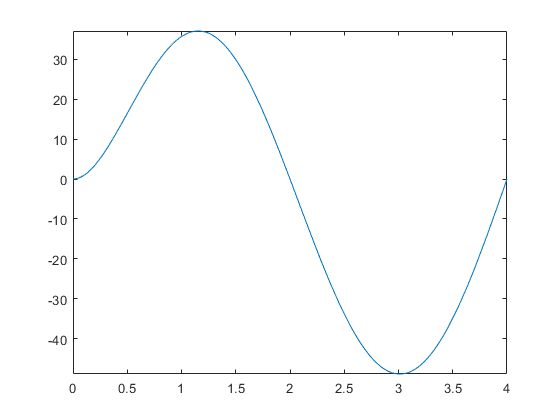

des_traj_handle = matlabFunction(des_traj_sym);
fplot(des_traj_sym) 
xlim([0 2*pi/omega_sim]); 

## Simulate the Integral Controller

%Specify simulation time
t_sim = 2*pi/omega_sim;
%Specify initial conditions
x1a_0 = [0 0 0 0 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system
%Select setpoint type
SP_sel = 1; %Sinusoidal input

out_Int = sim('Linear_Moving_Setpoint_SS');


## Augmented System For State Space Representation of a PID Controller

### Define Augmented State Vector


$$\tilde{x}_{1a} = [
 \int_0^t \!e_x\, \mathrm{d}t ~ e_x ~ e_\dot{x} ~ \beta~\dot{\beta}]^T


$$



$$\dot{\tilde{x}}_{1a} = [
e_x ~e_\dot{x} ~ e_\ddot{x}  ~\beta~\dot{\beta}]^T$$


Where $e_\dot{x}$ is the error in the $x$ direction velocity,


$$e_\dot{x} = \dot{x}_s - \dot{x}$$


and $\(\int_{0}^{t} e_x \,\mathrm{d}t\)$ is the error in the integral of the $x$ position, 


$$ \int_0^t \!e_x\, \mathrm{d}t  ~=~  \int_0^t \!x_s\,   -  x\, \mathrm{d}t  ~=~  \int_0^t \!x_s\, \mathrm{d}t   ~-~ \int_0^t \!x\, \mathrm{d}t $$


### Get Matrices for Augmented Dynamics

The new dynamics are found by differentiating the augmented state vector:


$$\dot{\tilde{x}}_{1a}  = 

\left\lbrack \begin{array}{c}

e_x\\ e_{\dot{x}}\\ e_{\ddot{x}}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack

= 

\left\lbrack \begin{array}{c}

x_s - x\\

\dot{x}_s - \dot{x}\\ 

\ddot{x}_s - \ddot{x}\\ 

\dot{\beta}\\ 

\ddot{\beta}\\



\end{array}\right\rbrack$$


This produces a matrix equation with the following form:


$$\dot{\tilde{x}}_{1a} = A_{1a}\tilde{x}_{1a} + B_{1a}T_\beta + S_{1a}{x}_{s}$$


### Get Matrices for Augmented Dynamics


$$\dot{\tilde{x}}_{1a} = A_{1a}\tilde{x}_{1a} + B_{1a}T_\beta + S_{1a}\tilde{x}_{1s}$$


Where $S_{1a}$ is the input matrix for the setpoint vector $\tilde{x}_{1s} = [x_s ~\dot{x}_s~\ddot{x}_s]$. $A_{1e}$ is the state coupling matrix for the augmented - error state vector $\tilde{x}_{1a}$ and $B_{1a}$ is the input matrix for torque $T_\beta$. 

stateVec1a = [e_ix, e_x, e_x_dot, beta, beta_dot].'; %State vector augmented with integral of the error in x AND x and x_dot replaced with error states
stateVec1a_dot = [e_x, e_x_dot, e_x_ddot, beta_dot, beta_ddot].';
x_1a_dot_eqn = stateVec1a_dot == [e_x e_x_dot (x_ddot_s - x_ddot) beta_dot rhs(LIN_EOMS1(4))].';
x_1a_dot_eqn = stateVec1a_dot == subs(rhs(x_1a_dot_eqn), x_ddot , rhs(LIN_EOMS1(2)));
x_1a_dot_eqn = subs(x_1a_dot_eqn, x, x_s - e_x);

A1a = equationsToMatrix(rhs(x_1a_dot_eqn), stateVec1a)

$$A1a = \left[\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & -5.2170 & 0 & -4.0111 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & -112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

B1a = equationsToMatrix(rhs(x_1a_dot_eqn), T_beta)

$$B1a = \left[\begin{array}{c} 0\\ 0\\ 17.7268\\ 0\\ 383.5785 \end{array}\right]$$


setpointVec1 = [x_s x_dot_s x_ddot_s].'

$$setpointVec1 = \left[\begin{array}{c} x_{s}\\ {\dot{x}}_{s}\\ {\ddot{x}}_{s} \end{array}\right]$$

S1a = equationsToMatrix(rhs(x_1a_dot_eqn), setpointVec1)

$$S1a = \left[\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 5.2170 & 0 & 1\\ 0 & 0 & 0\\ 112.8871 & 0 & 0 \end{array}\right]$$

The final equations of motion are:


$$

\left\lbrack \begin{array}{c}

e_x\\ e_{\dot{x}}\\ e_{\ddot{x}}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack

=

\left\lbrack \begin{array}{ccccc}
0 & -1 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0\\
0 & -5.2170 & 0 & 4.0111 & 0\\
0 & 0 & 0 & 0 & 1\\
0 & 112.8871 & 0 & 64.8295 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}

 \int_0^t \!e_x\, \mathrm{d}t\\ e_x\\ e_\dot{x}\\ \beta\\ \dot{\beta}\\



\end{array}\right\rbrack

+ 

\left\lbrack \begin{array}{c}
0\\
0\\
-17.7268\\
0\\
383.5785
\end{array}\right\rbrack


T_{\beta }

+ 

\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
5.2170 & 0 & 1\\
0 & 0 & 0\\
112.8871 & 0 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}
x_s \\
{\dot{x} }_s \\
{\ddot{x} }_s 
\end{array}\right\rbrack

$$


## Create Data and Functions for Simulation (PID Controller)

A1a_sim = double(A1a);
B1a_sim = double(B1a);
S1a_sim = double(S1a);

Check controllability

rank(ctrb(A1a_sim, B1a_sim))

ans = 5

The system is fully controllable because the controllability matrix is full rank

%Our desired control output is the x state (want it to match as closely as possible to x_s
%for all times)
%x = x_s - e_x 
C1a_setp_ctrl = [0 -1 0 0 0]; 
D1a_setp_ctrl = [1 0 0];

%This is for plotting x_s and x on the same scope
x_s_select = D1a_setp_ctrl;

### Find Integral and Derivatives of Trajectory

des_traj_sym_dot(t) = diff(des_traj_sym(t),t)

$$des\_traj\_sym\_dot(t) = 62.5000\,{\mathrm{e}}^{-1.2500\,t}\,\sin\left(1.5708\,t\right)-78.5398\,\cos\left(1.5708\,t\right)\,\left({\mathrm{e}}^{-1.2500\,t}-1\right)$$

des_traj_sym_ddot(t) = diff(des_traj_sym_dot(t),t)

$$des\_traj\_sym\_ddot(t) = 196.3495\,{\mathrm{e}}^{-1.2500\,t}\,\cos\left(1.5708\,t\right)-78.1250\,{\mathrm{e}}^{-1.2500\,t}\,\sin\left(1.5708\,t\right)+123.3701\,\sin\left(1.5708\,t\right)\,\left({\mathrm{e}}^{-1.2500\,t}-1\right)$$


%Create function handles from the desired trajectory information
des_traj_handle = matlabFunction([des_traj_sym;des_traj_sym_dot;des_traj_sym_ddot])

des_traj_handle = function_handle with value:
    @(t)[sin((t.*pi)./2.0).*(exp(t.*(-5.0./4.0))-1.0).*-5.0e+1;exp(t.*(-5.0./4.0)).*sin((t.*pi)./2.0).*(1.25e+2./2.0)-pi.*cos((t.*pi)./2.0).*(exp(t.*(-5.0./4.0))-1.0).*2.5e+1;exp(t.*(-5.0./4.0)).*sin((t.*pi)./2.0).*(-6.25e+2./8.0)+pi.^2.*sin((t.*pi)./2.0).*(exp(t.*(-5.0./4.0))-1.0).*(2.5e+1./2.0)+pi.*exp(t.*(-5.0./4.0)).*cos((t.*pi)./2.0).*(1.25e+2./2.0)]


### Place the poles of the closed loop transfer function 


$$\frac{{X_s}(s)}{X(s)}  = C_{1a}(SI - (A_{1a} - B_{1a}K_1))^{-1}S_{1a} + D_{1a}$$


where the matrices all belong to the augmented state space system. The effect is to avoid having to choose PID gains in an architecuture of the form


$$\frac{{X_s}(s)}{X(s)}  = \frac{C(s)P(s)}{1 + C(s)P(s)$$


where $C(s)$ is a PID controller and $P(s)$ is the open loop plant


$$P(s) = \frac{T_{\beta}(s)}{X(s)} = C_1(SI - A_1)^{-1}B_1$$
 

At the very least, this provides for bounded input - bounded output stability. However, this tells us nothing directly about the tracking performance of the controller. With the augmented system, we can simply use full state feedback to arbitrarily place the poles of the PID controller rather than having to use three dimensional root locus techniques in our choice of $K_i, ~K_p, ~and~K_d$. 

K1a = place(A1a_sim,B1a_sim, [-10 -20 -30 -4 -5]); 

## Simulate the PID Controller

out_PID = sim('Linear_Moving_Setpoint_SS');

## Compare the Responses

### Raw Simulation Data Plotted

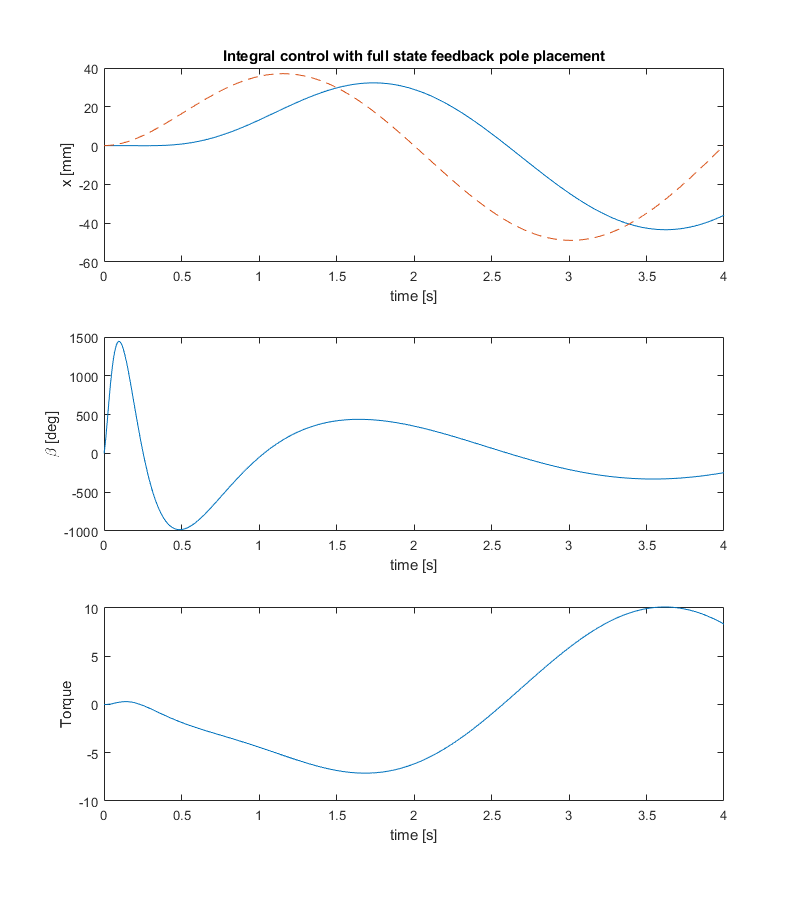

%Plot the integral controller results
figure
ax1 = subplot(3,1,1);
plot(out_Int.tout,out_Int.y1,out_Int.tout,out_Int.x_s_vec,'--' )
xlabel('time [s]')
ylabel('x [mm]')
title('Integral control with full state feedback pole placement')


ax2 = subplot(3,1,2);
plot(out_PID.tout,rad2deg(out_PID.x1a(:,3)))
xlabel('time [s]')
ylabel('\beta [deg]')


ax3 = subplot(3,1,3);
plot(out_Int.tout,out_Int.T_beta)
xlabel('time [s]')
ylabel('Torque')
linkaxes([ax1,ax2, ax3],'x');
set(gcf,'position',[0,0,800,900]);

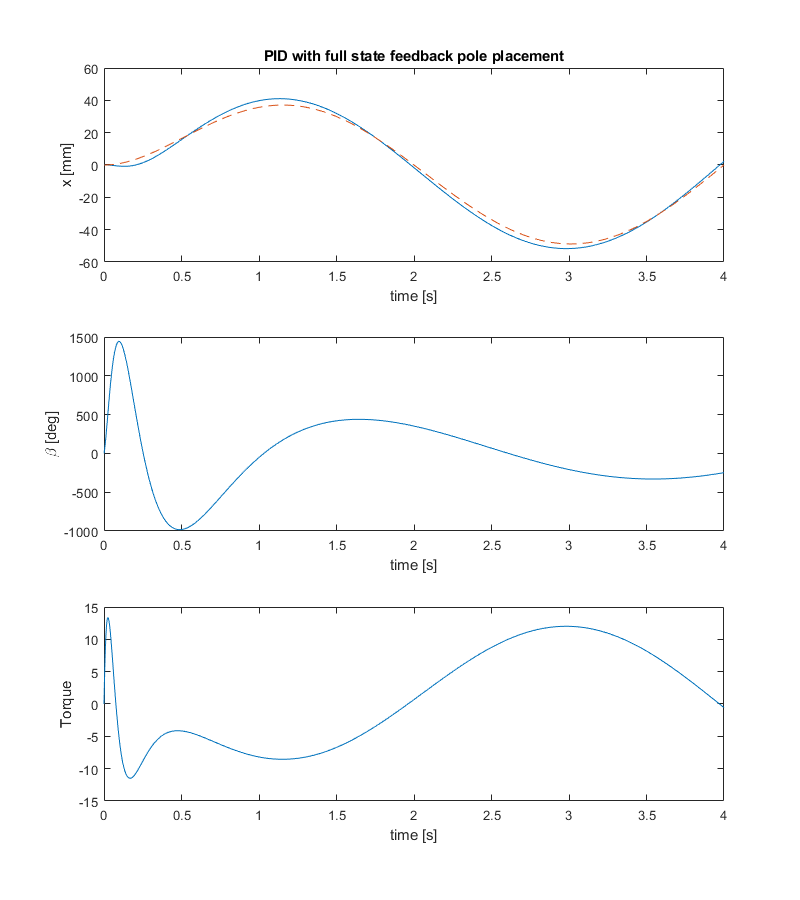


%Plot the PID controller results
figure
ax1 = subplot(3,1,1);
plot(out_PID.tout,out_PID.y1,out_PID.tout,out_PID.x_s_vec(:,1),'--' )
xlabel('time [s]')
ylabel('x [mm]')
title('PID with full state feedback pole placement')


ax2 = subplot(3,1,2);
plot(out_PID.tout,rad2deg(out_PID.x1a(:,3)))
xlabel('time [s]')
ylabel('\beta [deg]')


ax3 = subplot(3,1,3);
plot(out_PID.tout,out_PID.T_beta)
xlabel('time [s]')
ylabel('Torque')
linkaxes([ax1,ax2, ax3],'x');
set(gcf,'position',[0,0,800,900]);

### Trajectory Similarity Measure 1 - Dynamic Time Warping

First, compute the distance measure before the time warping for each trajectory

% dis_int_i = 

#### DTW - Integral Controller

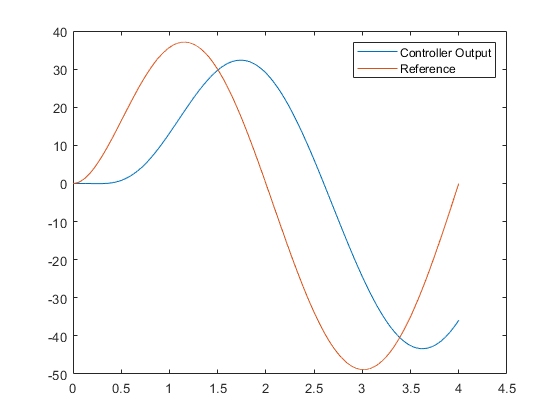

% First, resample the data at a fixed frequency
% t_samp_int = linspace(out_Int.tout(1),out_Int.tout(end),5*length(out_Int.tout)); %New sample points spaced at constant sample frequency
% f_samp_int = 1/(t_samp_int(2) - t_samp_int(1)) %Resampled frequency in Hz

% [y1_int, t_y1_int] = resample(out_Int.y1, out_Int.tout, 10000, 'linear');
y1_int = out_Int.y1;
t_y1_int = out_Int.tout;
[x_s_int, t_x_s_int] = resample(out_Int.x_s_vec, out_Int.tout, 100000, 'linear');

figure
plot(t_y1_int, y1_int,t_x_s_int,x_s_int)
legend('Controller Output', 'Reference')

[dist_int, i_wrp_trj_int, i_wrp_sp_int] = dtw(y1_int, x_s_int);

dist_int

dist_int = 1.2762e+06

dist_int/numel(i_wrp_trj_int)

ans = 3.1889

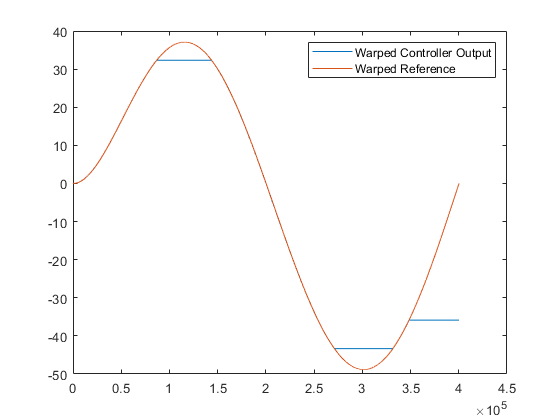


%t_warped = 0:numel(i_wrp_trj_int);%linspace(0,numel(i_wrp_trj_int)/f_samp_int, numel(i_wrp_trj_int));

figure
plot(1:numel(i_wrp_trj_int), y1_int(i_wrp_trj_int),1:numel(i_wrp_trj_int), x_s_int(i_wrp_sp_int))
legend('Warped Controller Output', 'Warped Reference')

#### DTW - PID Controller

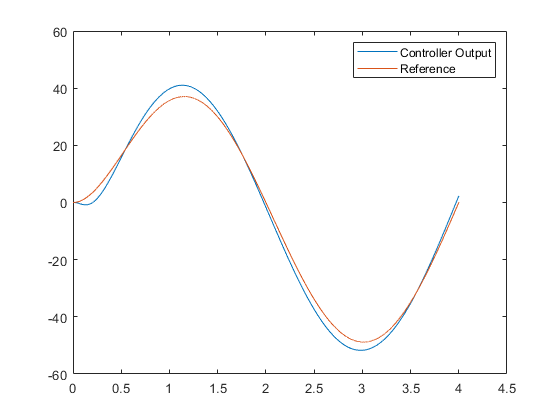

% First, resample the data at a fixed frequency
% t_samp_int = linspace(out_Int.tout(1),out_Int.tout(end),5*length(out_Int.tout)); %New sample points spaced at constant sample frequency
% f_samp_int = 1/(t_samp_int(2) - t_samp_int(1)) %Resampled frequency in Hz

% [y1_PID, t_y1_PID] = resample(out_PID.y1, out_PID.tout, 1000, 'linear');
y1_PID = out_PID.y1(:,1);
t_y1_PID = out_PID.tout;
[x_s_PID, t_x_s_PID] = resample(out_PID.x_s_vec(:,1), out_PID.tout, 100000, 'linear');

figure
plot(t_y1_PID, y1_PID,t_x_s_PID,x_s_PID)
legend('Controller Output', 'Reference')


[dist_PID, i_wrp_trj_pid, i_wrp_sp_pid] = dtw(y1_PID, x_s_PID);

dist_PID %Sum of Euclidian distances of the links

dist_PID = 2.7318e+04

dist_PID/numel(i_wrp_trj_pid) %Average Euclidian distance of the links

ans = 0.0682

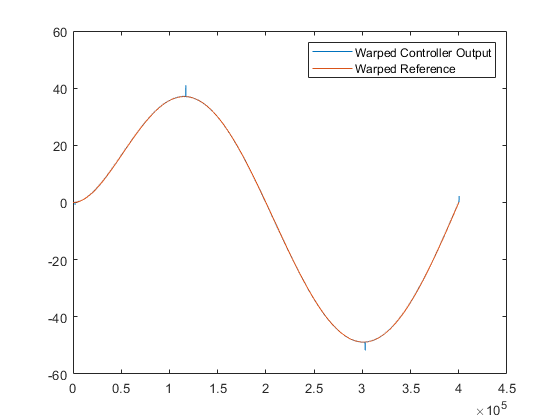


figure
plot(1:length(i_wrp_trj_pid), y1_PID(i_wrp_trj_pid),1:length(i_wrp_trj_pid), x_s_PID(i_wrp_sp_pid))
legend('Warped Controller Output', 'Warped Reference')